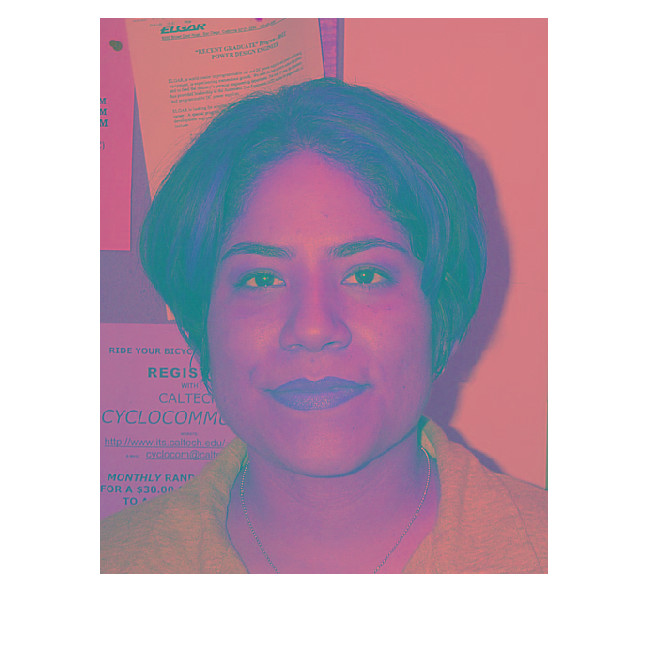

% light compensation

img = imread("../TNM034/Facial-recognition/facedetection/");


% binary image 
bin_img = zeros(size(img,1),size(img,2));

% YCbCr
YCbCr_img = rgb2ycbcr(img);
%C1 = double(YCbCr_img);
imshow(YCbCr_img)

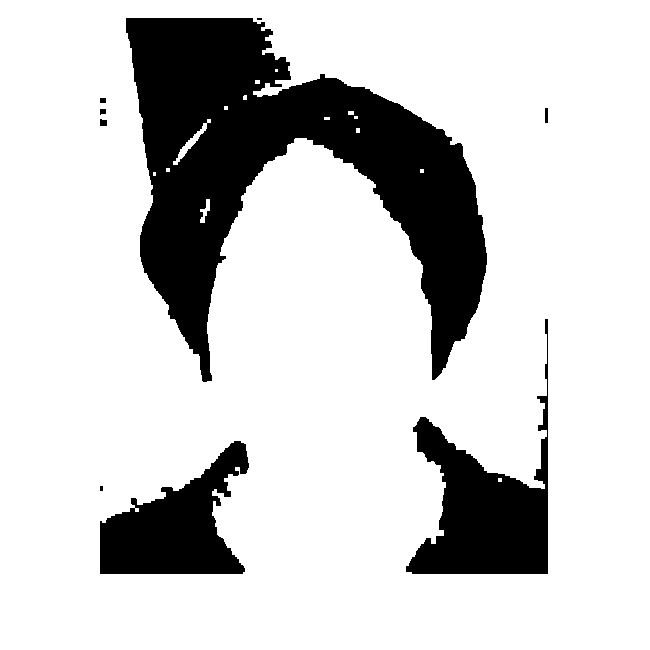


y=YCbCr_img(:,:,1);
cb=YCbCr_img(:,:,2);
cr=YCbCr_img(:,:,3);

% Threshold
[row,col] = find(cb > 77 & cb < 200 & cr >= 130 & cr < 178 & y >=80);

% Change skin color

for k = 1:size(row)
    bin_img(row(k),col(k)) = 1;
end

% Morphology
SE = strel('square',4);
bin_img = imopen(bin_img, SE);
bin_img = imclose(bin_img, SE);

bin_img = imfill(bin_img, 'holes');
target = 256:-4:4;
bin_img = histeq(bin_img,target);
bin_img = imbinarize(bin_img,0.9);

binary_img = bwareafilt(bin_img,1);
imshow(bin_img)